`Erfan Panahi   810198369`

## Digital Signal Processing (DSP)

# Computer Assignement 3

## ***Contents:***

***    Part 1 . Audio signal processing***

`    - Echo Cancellation `

`    - Noise Restriction`

***    Part 2 . Image Processing***

# `Part 1:`***Audio signal processing***

 `(+)`` making a noisy echoed voice:`

clear;
[input,fs] = audioread('input_voice.wav');
input = transpose(input);
%echo:
Beta = 4410;
Alpha = 0.8;
echoed_voice = [input zeros(1,Beta)] + [zeros(1,Beta) Alpha*input];
%noise:
pre_noise = randn(size(echoed_voice));
noise = 0.2*pre_noise/max(pre_noise);
%noisy_echoed_voice
noisy_echoed_voice = noise + echoed_voice;
audiowrite('noisy_echoed_voice.wav',noisy_echoed_voice,fs);
%sound(noisy_echoed_voice,fs);


## `Problem 1: Echo Cancellation `

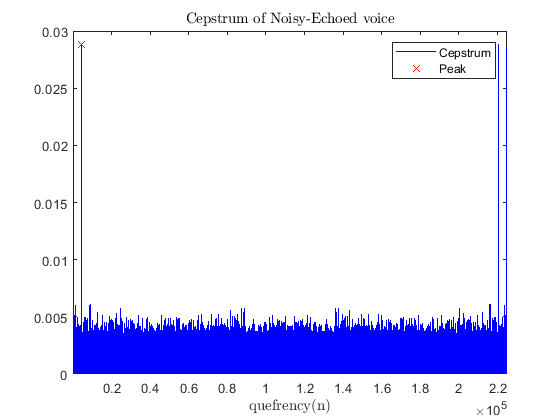

[BetaRec,noisy_voice] = CancelEcho(noisy_echoed_voice,Alpha);

%sound(noisy_voice,fs);
audiowrite('noisy_voice.wav',noisy_voice,fs);
fprintf('Beta = %d \nReconstructed Beta =  %d \nDelay in time domain = %.1f sec',Beta,BetaRec,Beta/fs);

Beta = 4410 
Reconstructed Beta =  4410 
Delay in time domain = 0.2 sec

`Time and freuency domain:`

L = length(noisy_echoed_voice);
Ts = 1/fs;
f = -fs/2:fs/L:fs/2-1/L;
t = Ts*(0:L-1);
NOISY_ECHOED_VOICE = fftshift(fft(noisy_echoed_voice))/L;
NOISY_VOICE = fftshift(fft(noisy_voice))/L;

`Plot:`

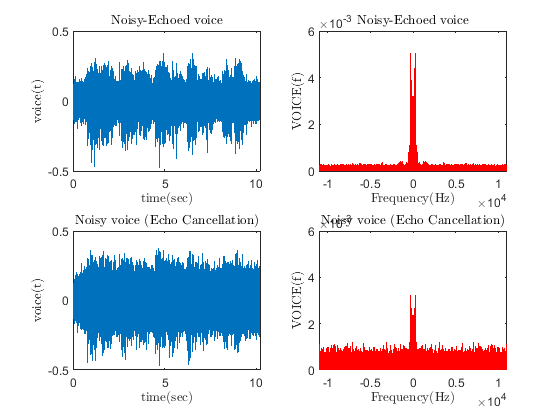

subplot(2,2,1);
plot(t,noisy_echoed_voice);
xlim([0 10.2]);
title('Noisy-Echoed voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(2,2,2);
plot(f,abs(NOISY_ECHOED_VOICE),'r');
xlim([-fs/2 fs/2]);
title('Noisy-Echoed voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');
subplot(2,2,3);
plot(t,noisy_voice);
xlim([0 10.2]);
title('Noisy voice (Echo Cancellation)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(2,2,4);
plot(f,abs(NOISY_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Noisy voice (Echo Cancellation)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');

## `Problem 2: Noise Restriction`

BandPassFilter = ExportedFilter;
reconstructed_voice = conv(noisy_voice,BandPassFilter,'same');
sound(reconstructed_voice,fs);
audiowrite('reconstructed_voice.wav',reconstructed_voice,fs);
RECONSTRUCTED_VOICE = fftshift(fft(reconstructed_voice))/L;
INPUT_VOICE = fftshift(fft([input zeros(1,Beta)]))/L;

`Plot:`

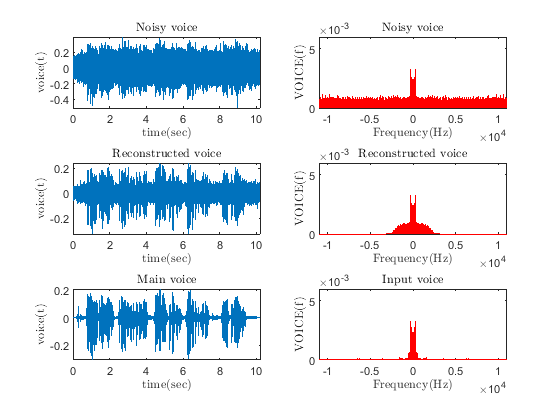

subplot(3,2,1);
plot(t,noisy_voice);
xlim([0 10.2]);
title('Noisy voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,2);
plot(f,abs(NOISY_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Noisy voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');
subplot(3,2,3);
plot(t,reconstructed_voice);
xlim([0 10.2]);
title('Reconstructed voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,4);
plot(f,abs(RECONSTRUCTED_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Reconstructed voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');
subplot(3,2,5);
plot(t,[input zeros(1,Beta)]);
xlim([0 10.2]);
title('Main voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,6);
plot(f,abs(INPUT_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Input voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');

`Another filter:`

BandPassFilter2 = ExportedFilter2;
reconstructed_voice2 = conv(noisy_voice,BandPassFilter2,'same');
sound(reconstructed_voice2,fs);
audiowrite('reconstructed_voice2.wav',reconstructed_voice2,fs);
RECONSTRUCTED_VOICE2 = fftshift(fft(reconstructed_voice2))/L;
INPUT_VOICE = fftshift(fft([input zeros(1,Beta)]))/L;

`Plot:`

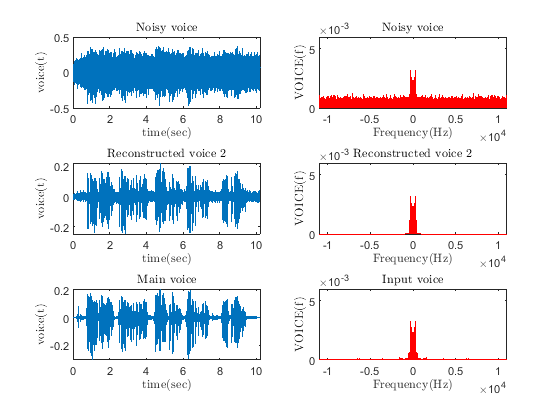

subplot(3,2,1);
plot(t,noisy_voice);
xlim([0 10.2]);
title('Noisy voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,2);
plot(f,abs(NOISY_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Noisy voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');
subplot(3,2,3);
plot(t,reconstructed_voice2);
xlim([0 10.2]);
title('Reconstructed voice 2','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,4);
plot(f,abs(RECONSTRUCTED_VOICE2),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Reconstructed voice 2','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');
subplot(3,2,5);
plot(t,[input zeros(1,Beta)]);
xlim([0 10.2]);
title('Main voice','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('voice(t)','Interpreter','latex');
subplot(3,2,6);
plot(f,abs(INPUT_VOICE),'r');
xlim([-fs/2 fs/2]);
ylim([0 6e-3]);
title('Input voice','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('VOICE(f)','Interpreter','latex');

`Amplifing the reconstructed voice 2:`

reconstructed_amp_voice2 = 3 * reconstructed_voice2;
sound(reconstructed_amp_voice2,fs);

# `Part 2: Image Processing`

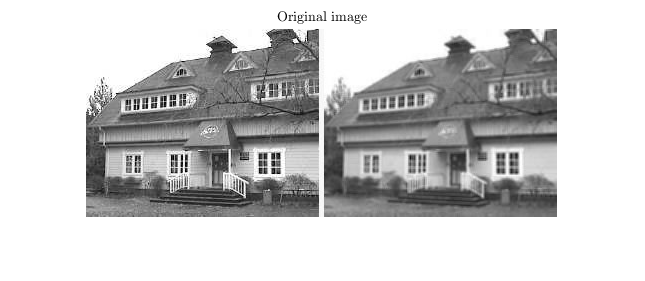

clear;
WindowSize = 3;
house_rgb = imread('house.jpg');
house = rgb2gray(house_rgb);
imshow(house);
title('Original image','Interpreter','latex');

- `Identity:`

Identity = zeros(WindowSize); Identity(2,2) = 1;
Identity_out = conv2(house,Identity);
subplot(4,2,1);
Fig = figure(1);
set(Fig,'Position',[0 0 1000 1000]);
imshow(uint8(Identity_out));
title('Identity','Interpreter','latex');

- `V-line`

Vline = -1 * ones(WindowSize); Vline(:,2) = 2;
Vline_out = conv2(house,Vline);
subplot(4,2,2);
imshow(abs(uint8(Vline_out)));
title('V-line','Interpreter','latex');

- `H-line:`

Hline = -1 * ones(WindowSize); Hline(2,:) = 2;
Hline_out = conv2(house,Hline);
subplot(4,2,3);
imshow(abs(uint8(Hline_out)));
title('H-line','Interpreter','latex');

- `Moving Average:`

MovingAvg = ones(WindowSize)/WindowSize^2;
MovingAvg_out = conv2(house,MovingAvg);
subplot(4,2,4);
imshow(uint8(MovingAvg_out));
title('Moving Average','Interpreter','latex');

- `Gaussian (`$\sigma =0\ldotp 5$`):`

Sigma = 0.5;
Gauss = fspecial('gaussian',[WindowSize WindowSize],Sigma);
Gauss_out = conv2(house,Gauss);
subplot(4,2,5);
imshow(uint8(Gauss_out));
title('Gaussian','Interpreter','latex');

- `Outline:`

Outline = -1 * ones(WindowSize); Outline(2,2) = 8;
Outline_out = conv2(house,Outline);
subplot(4,2,6);
imshow(abs(uint8(Outline_out)));
title('Outline','Interpreter','latex');

- `Blur:`

Blur = [1/16 1/8 1/16;
        0/8  1/2  1/8;
        1/16 1/8 1/16];
Blur_out = conv2(house,Blur);
subplot(4,2,7);
imshow(uint8(Blur_out));
title('Blur','Interpreter','latex');

- `Sharpen:`

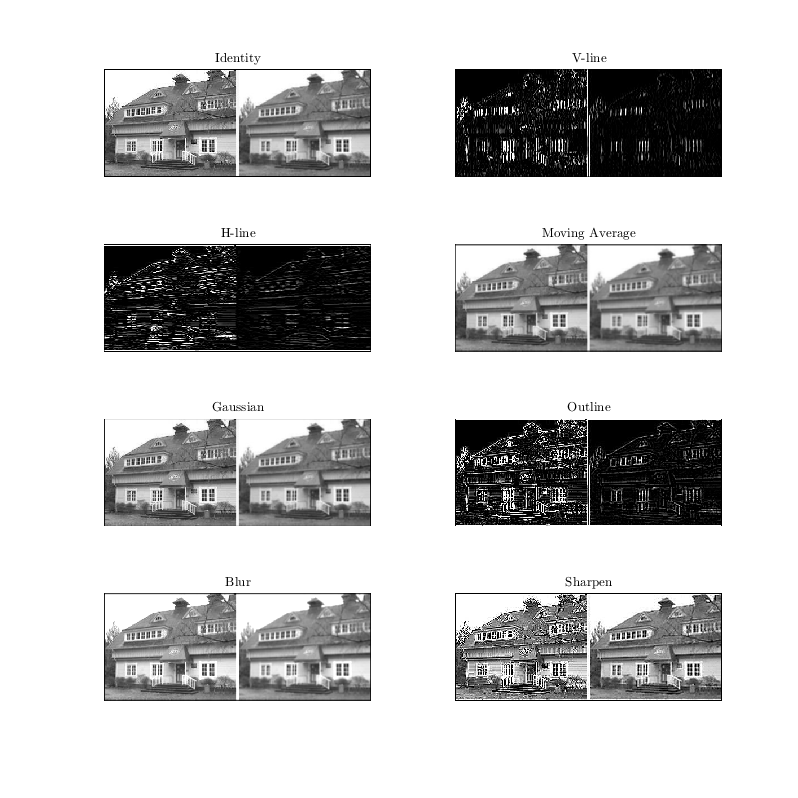

Sharpen = [0 -1 0;
           -1 5 -1;
           0 -1 0];
Sharpen_out = conv2(house,Sharpen);
subplot(4,2,8);
imshow(abs(uint8(Sharpen_out)));
title('Sharpen','Interpreter','latex');

`Resizing and Interpolation:`

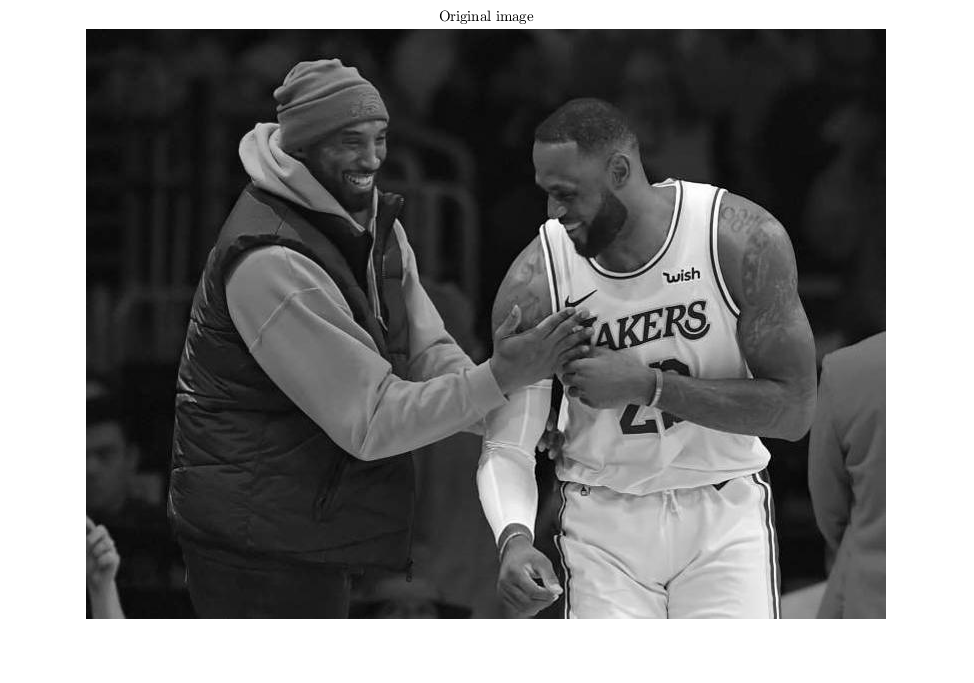

kobe_rgb = imread('kobe.jpeg');
kobe = rgb2gray(kobe_rgb);
imshow(kobe);
title('Original image','Interpreter','latex');

- `Resizing (`$\frac{1}{5}$`):`

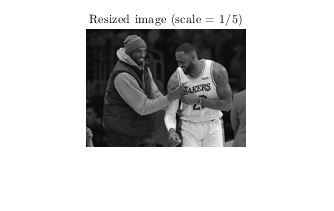

kobe1_5 = imresize(kobe,1/5);
imshow(kobe1_5);
title('Resized image (scale = $1/5$)','Interpreter','latex');

- `Resizing (`$5$`):`

kobe5 = imresize(kobe1_5,5,'nearest');
Fig2 = figure(2);
subplot(3,1,1);
imshow(kobe5);
set(Fig2,'Position',[0 0 2000 2500]);
title('Resized image (scale = 5)','Interpreter','latex');

- `Moving Average:`

MovingAvg_kobe = conv2(kobe5,MovingAvg);
subplot(3,1,2);
imshow(uint8(MovingAvg_kobe));
title('Moving Average','Interpreter','latex');

- `Gaussian (`$\sigma =0\ldotp 5$`):`

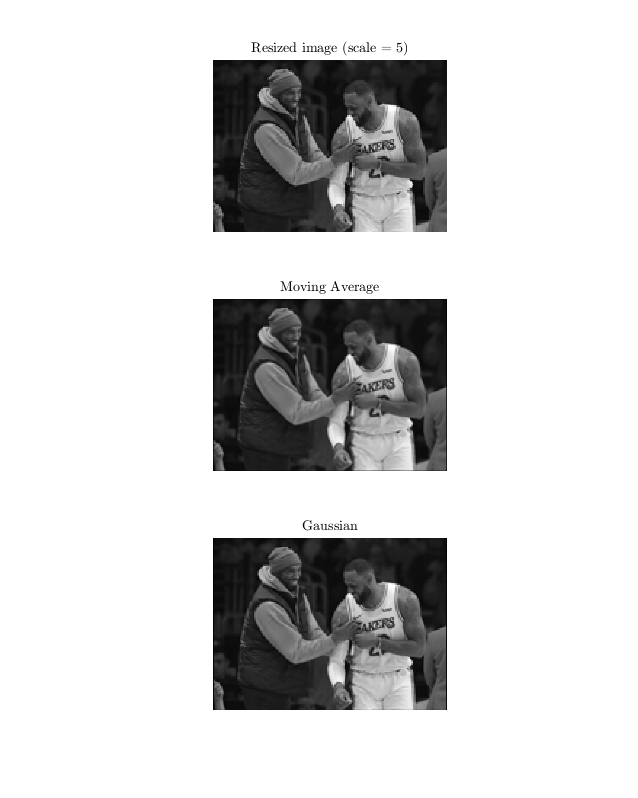

Gauss_kobe = conv2(kobe5,Gauss);
subplot(3,1,3);
imshow(uint8(Gauss_kobe));
title('Gaussian','Interpreter','latex');

- `Page localization:`

warning('off','all');
Fig3 = figure(3);
page_rgb = imread('page.jpg');
page = rgb2gray(page_rgb);
subplot(1,3,1);
imshow(page);
set(Fig3,'Position',[0 0 2000 500]);
title('Original image','Interpreter','latex');

- `V-line`

Vline_page = conv2(page,Vline);
subplot(1,3,2);
imshow(abs(uint8(Vline_page)));
title('V-line','Interpreter','latex');

- `H-line:`

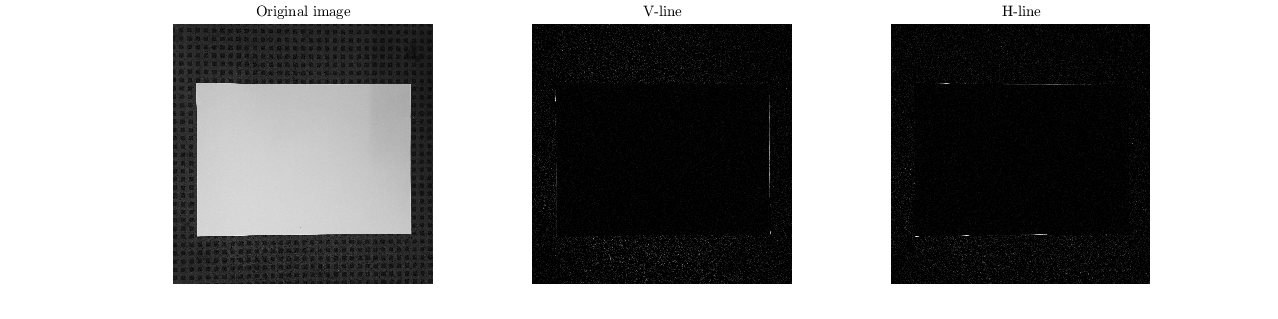

Hline_page = conv2(page,Hline);
subplot(1,3,3);
imshow(abs(uint8(Hline_page)));
title('H-line','Interpreter','latex');

`Using the H line and V line kernel we write a function (ObjLoc) to find the edge of a page:`

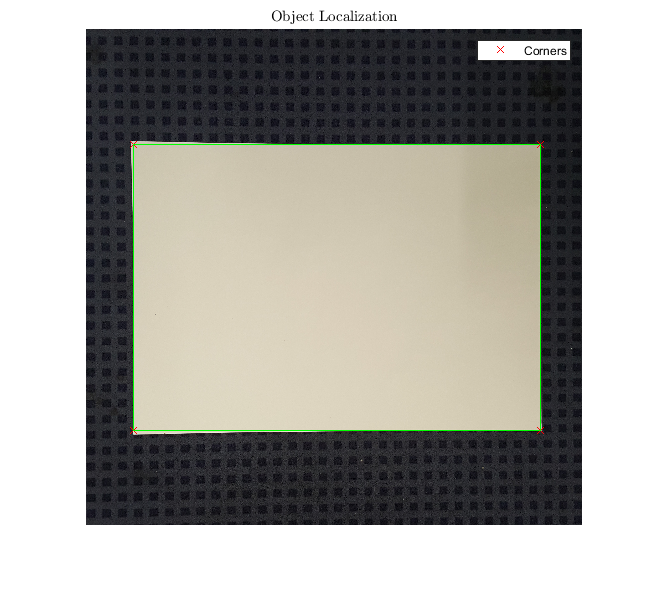

ObjLoc(page_rgb);

- `Another test-case:`

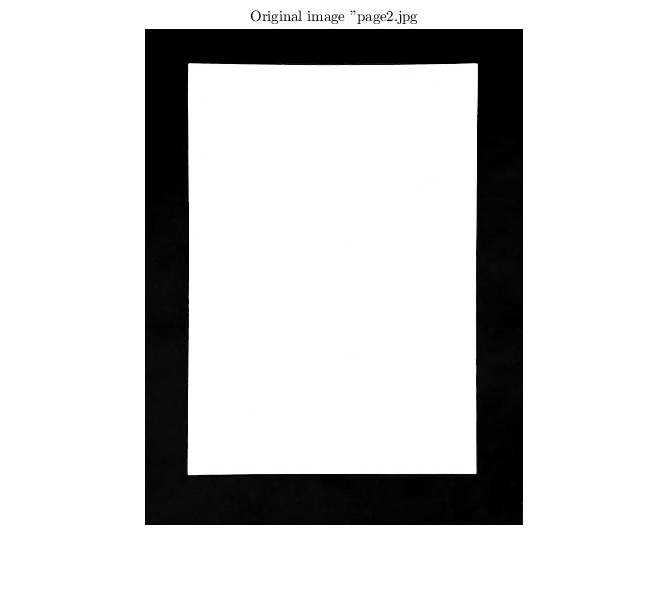

warning('off','all');
page2_rgb = imread('page2.jpg');
page2 = rgb2gray(page2_rgb);
imshow(page2);
title('Original image "page2.jpg','Interpreter','latex');

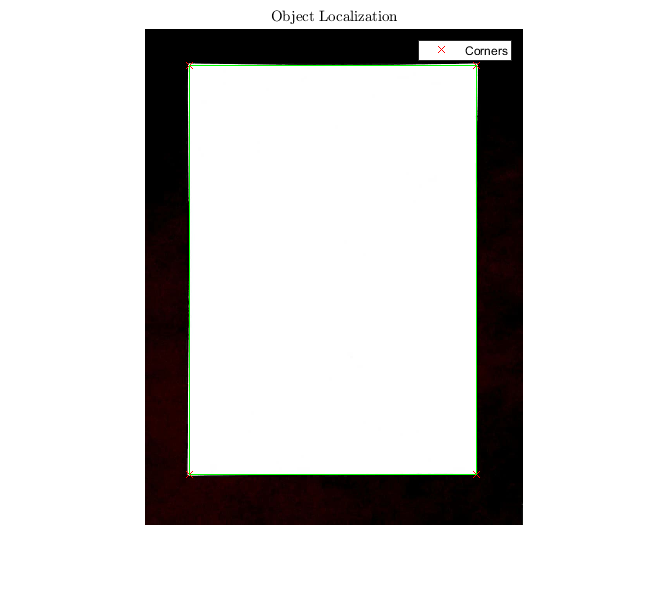

ObjLoc(page2_rgb);

# `Functions:`

`Echo Cancellation:`

function [Beta,noisy_voice] = CancelEcho(noisy_echoed_voice,Alpha)
    CepsNEVoice = rceps(noisy_echoed_voice);
    Beta_plus1 = find(CepsNEVoice == max(CepsNEVoice(10:length(CepsNEVoice)/2)),1,'first');
    Beta = Beta_plus1 - 1;
    H(1) = 1;
    H(Beta+1) = Alpha;
    noisy_voice = filter(1,H,noisy_echoed_voice);
    n = 10:length(CepsNEVoice)-10;
    plot(n,abs(CepsNEVoice(10:length(CepsNEVoice)-10)),'b',Beta+1,abs(CepsNEVoice(Beta+1)),'rx');
    xlim([10 length(CepsNEVoice)-10]);
    legend('Cepstrum','Peak');
    title('Cepstrum of Noisy-Echoed voice','Interpreter','latex');
    xlabel('quefrency(n)','Interpreter','latex');
end

`Object Localization:`

function ObjLoc(pageRGB)
    page = rgb2gray(pageRGB);
    WindowSize = 3;
    Hline = -1 * ones(WindowSize); Hline(2,:) = 2;
    Vline = -1 * ones(WindowSize); Vline(:,2) = 2;
    Hline_page = conv2(page,Hline);
    Vline_page = conv2(page,Vline);
    Hvalues = sum(abs(uint8(Hline_page')));
    Vvalues = sum(abs(uint8(Vline_page)));
    Hmax = maxk(Hvalues(10:length(Hvalues)-10),2);
    Vmax = maxk(Vvalues(10:length(Vvalues)-10),2);
    H(1) = find(Hvalues == Hmax(1)); H(2) = find(Hvalues == Hmax(2)); 
    V(1) = find(Vvalues == Vmax(1)); V(2) = find(Vvalues == Vmax(2));
    H1 = min(H); H2 = max(H); V1 = min(V); V2 = max(V);  
    imshow(pageRGB);
    hold on
    plot([V1 V2 V1 V2],[H1 H1 H2 H2],'rx');
    rectangle('Position',[V1 H1 V2-V1 H2-H1],'EdgeColor','g');
    title('Object Localization','Interpreter','latex');
    legend('Corners');
    hold off
end